# Control de sistemas biológicos TP N°1

A continuación se resuelve el problema 1 de la práctica N°1.

El modelo a controlar es el siguiente:

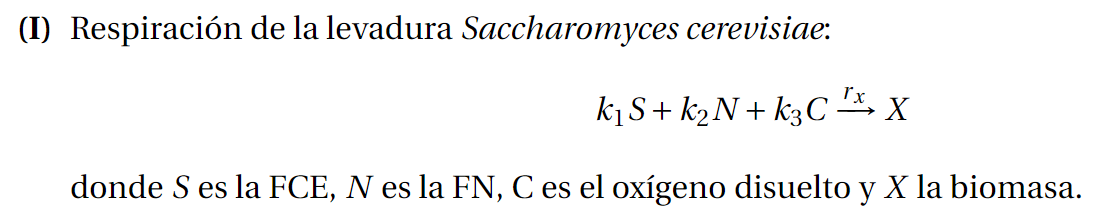

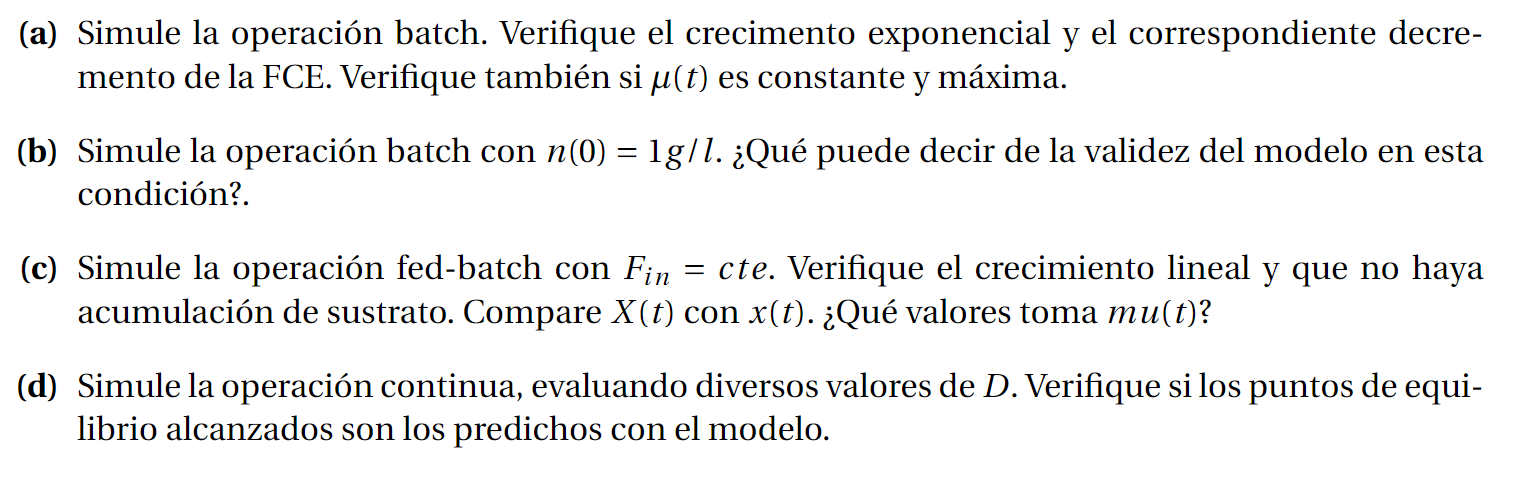

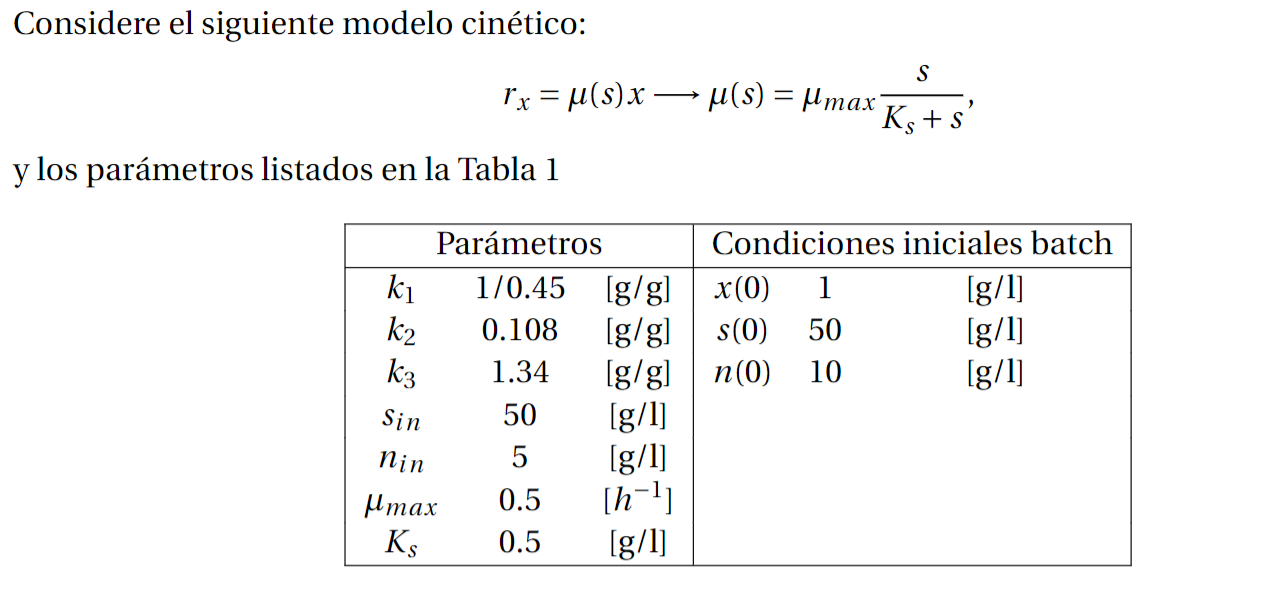

clc; clear all;

## Preguntas

- En el inciso b obtengo el mismo resultado, qué está fallando?

- En el inciso c, qué es lo que se alimenta constantemente? el sustrato?

- La biomasa no debería tender a $\mu_{\max }$?

- Interpretaciones para los diferentes valores de D?

Defino los parámetros del modelo para un batch con modelo de Monod

% Datos dados
mumax=0.5;
Ks=0.5;
k1=1/0.45;
k2=0.108;
k3=1.34;
K=[1; -k1; -k2; -k3];

s_in=50;
n_in=5;
x0=1;
s0=50;
% n0=10;
n0=50;
Fin_s = 0;
Fin_n = 0;
Fin_c = 8;

% Creamos una estructura para pasar los parámetros al bloque función u
% otros bloques
modelParameters.mumax=mumax;
modelParameters.Ks=Ks;
modelParameters.K=K;

% Definimos entradas y condiciones iniciales
xi_in=[0;s_in;n_in;0];
Ds=[0.001, 0.01, 0.1, 1];
xi0=[1;50;10;50];
F=[0;Fin_s; Fin_n; Fin_c];
Q=[0;0;0;0];

for i=1:length(Ds)

    D=Ds(i);

    simConfig.StopTime = "50";
    sim_out = sim('TP1\basicModelWithMonod.slx', simConfig);
    
    % Grafico los resultados de la simulación
    time = sim_out.simout.Time;
    biomass = reshape(sim_out.simout.Data(1,1,:), size(time));
    sustrate = reshape(sim_out.simout.Data(2,1,:), size(time));
    nitrogen = reshape(sim_out.simout.Data(3,1,:), size(time));
    oxigen = reshape(sim_out.simout.Data(4,1,:), size(time));
    
    time_biomass_cero = time(find(sustrate > 0.2095, 1, 'last'));
    
    fig = figure();
    hold on; grid on;
    title(sprintf('Concentraciones para D=%.3f', D));
    xlabel('tiempo [Horas]');
    ylabel('Concentración [g/g]');
    ylim([0 max(sustrate)]);
    % xlim([0 time_biomass_cero]);
    
    plot(time, biomass, 'r', 'LineWidth', 3);
    plot(time, sustrate, 'b', 'LineWidth', 3);
    plot(time, nitrogen, 'k', 'LineWidth', 3);
    plot(time, oxigen, 'm', 'LineWidth', 3);
    
    legend('Biomasa', 'Sustrato', 'Nitrogeno', 'Oxigeno');
end